pd = pwd;
base_dir = fileparts(fileparts(pd));
addpath(base_dir)
init_tcm

## load basic data

files = get_exp_info_cfrl('cdcfr2');
real = load(files.data);
sem = load(files.wikiw2v.raw);

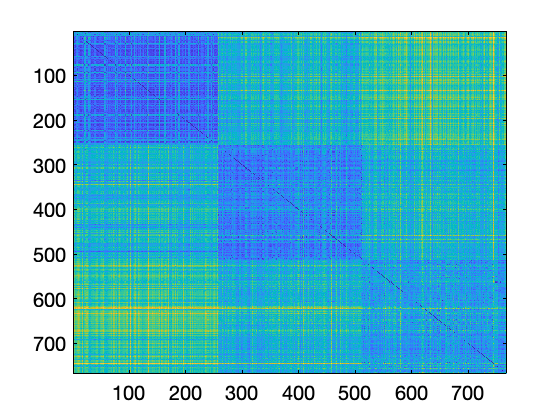

imagesc(sem.rdm)

## testing out logl model fits

% based on search with 10 replications, relatively lax finish
% criterion (0.01 threshold, 100 generations stall)

% prepare semantic CRP analysis (only have to run once)
create_sem_crp_bins(real.data, sem.sem_mat, files.wikiw2v.bin);

Undefined function or variable 'item_crp'.

Error in create_sem_crp_bins (line 13)
[actual, possible] = item_crp(data.recalls, data.pres_itemnos, ...


% make standard plots, get some stats
fig_dir = '~/work/cfr/figs';
%fits = {'data' 'base' 'wikiw2v_context' 'wikiw2v_item' 'wikiw2v_context_item'};
fits = {'data' 'full_wikiw2v'};
lbc_scores = NaN(29, length(fits));
cat_types = {'within' 'from' 'to'};
[~, ind] = unique(real.data.pres_itemnos);
category = real.data.pres.category(ind);
for i = 1:length(fits)
    disp(fits{i})
    info = get_fit_info_cfrl(fits{i}, 'cfr');
    load(info.stat_file);
    res_dir = fullfile(fig_dir, fits{i});
    if ~exist(res_dir, 'dir')
        mkdir(res_dir)
    end
    
    % standard catfr analyses
    print_spc_cat(data, fullfile(res_dir, 'spc_cat.eps'), 'spc');
    print_spc_cat(data, fullfile(res_dir, 'pfr_cat.eps'), 'pfr');
    print_crp_cat(data, 1, 'cat', fullfile(res_dir, 'crp_within_cat.eps'));
    print_crp_cat(data, 2, 'cat', fullfile(res_dir, 'crp_from_cat.eps'));
    print_crp_cat(data, 3, 'cat', fullfile(res_dir, 'crp_to_cat.eps'));

    % category clustering
    rec_mask = make_clean_recalls_mask2d(data.recalls);
    s_lbc = lbc(data.pres.category, data.rec.category, data.subject, ...
                'recall_mask', rec_mask);
    lbc_scores(:,i) = s_lbc;

    % probability of within-category transition, conditional on the
    % category of the previous recall
    print_clust_cat(data, fullfile(res_dir, 'clust_cat.eps'));
    
    % semantic crp
    bin = load(files.wikiw2v.bin);
    [act, poss] = item_crp(data.recalls, ...
                           data.pres_itemnos, ...
                           data.subject, ...
                           length(sem.sem_mat));
    print_sem_crp(act, poss, sem.sem_mat, bin.edges, bin.centers, ...
                  fullfile(res_dir, 'sem_crp.eps'));
    print_sem_crp(act, poss, sem.sem_mat, bin.edges, bin.centers, ...
                  fullfile(res_dir, 'sem_crp_within.eps'), ...
                  'mask', category == category');
    print_sem_crp(act, poss, sem.sem_mat, bin.edges, bin.centers, ...
                  fullfile(res_dir, 'sem_crp_between.eps'), ...
                  'mask', category ~= category');
end

## test out context decoding with added noise

% run a quick fit to get some parameters
data = getfield(load('cfr_benchmark_data.mat', 'data'), 'data');
[logl, logl_all, param, seq] = run_logl_fit(data);

% run an actual fit of one subject, with relatively lax optimization
res = indiv_search_cfrl('cfr', 'full_wikiw2v', 'n_workers', 1, ...
                        'search_type', 'de_fast', 'subject', 1);

stats = plot_subj_sim_results(res);

% set up decoding
labels = data.pres.category';
labels = labels(:);
targets = zeros(length(labels), 3);
for i = 1:3
    targets(labels==i,i) = 1;
end
list = repmat([1:30]', [1 24])';
list = list(:);
c = stats.net.pres.c';
pattern = cat(2, c{:})';

% run decoding
opt = struct;
opt.f_train = @train_logreg;
opt.train_args = {struct('penalty', 10)};
opt.f_test = @test_logreg;

% target is 58.9%
target_perf = .589;
n = linspace(.05, .25, 11);
n_rep = 10;
perf = NaN(length(n), n_rep);
for i = 1:length(n)
    for j = 1:n_rep
        noise = randn(size(pattern)) * n(i);
        res = xval(pattern+noise, list, targets, opt);
        perf(i,j) = mean([res.iterations.perf]);
    end
end
[~, ind] = min(abs(mean(perf, 2) - target_perf));
n_target = n(ind);

% calculate average evidence over many replications, for the
% best-matching noise level
n_rep = 100;
evidence_all = NaN(size(targets, 1), size(targets, 2), n_rep);
perf = NaN(1, n_rep);
for i = 1:n_rep
    noise = randn(size(pattern)) * n_target;
    res = xval(pattern+noise, list, targets, opt);
    perf(i) = mean([res.iterations.perf]);
    for k = 1:length(res.iterations)
        test_ind = res.iterations(k).test_idx;
        evidence_all(test_ind,:,i) = res.iterations(k).acts';
    end
end

% unpack evidence for each category on each trial
evidence = mean(evidence_all, 3);

% plot individual lists
colors = get(groot, 'defaultAxesColorOrder');
for i = 1:30
    clf
    hold on
    ind = list == i;
    for j = 1:3
        plot(evidence(ind,j), '-', 'Color', colors(j,:));
        plot(targets(ind,j), 'o', 'Color', colors(j,:));
    end
    pause
end

% sort by curr, prev, base
mat = struct;
[mat.curr, mat.prev, mat.base, mat.trainpos] = ...
    train_category(data.pres.category);

subject = repmat(data.subject, [1 24]);
v_subject = subject';
v_subject = v_subject(:);
usubject = unique(data.subject);

vec = struct;
f = fieldnames(mat);
for i = 1:length(f)
    m = mat.(f{i})';
    vec.(f{i}) = m(:);
end

n_subj = length(unique(data.subject));
x = NaN(n_subj, 3, 6, 3);
ttype = {'curr' 'prev' 'base'};
for i = 1:n_subj
    for j = 1:length(ttype)
        tvec = vec.(ttype{j});
        for k = 1:6
            for l = 1:3
                ind = v_subject == usubject(i) & ...
                      vec.trainpos == k & ...
                      tvec == l;
                x(i,j,k,l) = nanmean(evidence(ind,l));
            end
        end
    end
end

clf
y = squeeze(mean(x, 4));
plot(y');
l = legend(ttype);
ylabel('classifier evidence');
xlabel('train position');

## look at results from a search

fig_dir = '~/work/cfr/tests';
for i = 1:length(res)
    param = unpack_param(res(i).parameters, ...
                         res(i).fstruct.param_info, res(i).fstruct)
    param = check_param_cfrl(param);
    subj_data = res(i).fstruct.data;
    [logl, logl_all] = logl_tcm(param, subj_data);
    plot_logl_all(logl_all, subj_data.recalls, [5 6], [10 500]);
    subjno = sprintf('%02d', subj_data.subject(1));
    print(gcf, '-dpng', fullfile(fig_dir, ...
                                 sprintf('logl_all_%s.png', subjno)));
end

experiment = 'cfr';
fits = {'local' 'cat' 'wikiw2v' ...
        'local_cat' 'local_wikiw2v' 'cat_wikiw2v' ...
        'local_cat_wikiw2v'};
n_subj = 29;
fitness = NaN(n_subj, length(fits));
for i = 1:length(fits)
    info = get_fit_info_cfrl(fits{i}, experiment);
    s = load(info.res_file);
    fitness(:,i) = cat(1, s.stats.fitness);
end

for i = 1:length(fits)
    fprintf('%20s ', fits{i});
end
fprintf('\n');
for i = 1:n_subj
    for j = 1:length(fits)
        fprintf('%20.1f ', fitness(i,j));
    end
    fprintf('\n');
end

res_dir = '~/work/cfr/figs2';
all_fits = [{'data'} fits];
for i = 1:length(all_fits)
    fig_dir = fullfile(res_dir, all_fits{i});
    if ~exist(fig_dir, 'dir')
        mkdir(fig_dir)
    end
    print_fit_summary(all_fits{i}, experiment, fig_dir);
end

## clustering statistics summary

fits = {'data' 'local' 'cat' 'wikiw2v' ...
        'local_cat' 'local_wikiw2v' 'cat_wikiw2v' ...
        'local_cat_wikiw2v'};
fit_names = {'data' 'I' 'C' 'S' 'IC' 'IS' 'CS' 'ICS'};
experiments = repmat({'cfr'}, length(fits), 1);
stats = fit_clust_stats(fits, experiments);

close all
fig_dir = '~/work/cfr/figs2';
inc = [2:4 8 1];
print_fit_clust(stats.temp(:,inc), 'temp', fit_names(inc), ...
                fullfile(fig_dir, 'clust_temp.eps'));
print_fit_clust(stats.cat(:,inc), 'cat', fit_names(inc), ...
                fullfile(fig_dir, 'clust_cat.eps'));
print_fit_clust(stats.sem(:,inc), 'sem', fit_names(inc), ...
                fullfile(fig_dir, 'clust_sem.eps'));

print_fit_clust_range(stats.temp, 'temp', fit_names, ...
                      fullfile(fig_dir, 'clust_range_temp.eps'));
print_fit_clust_range(stats.cat, 'cat', fit_names, ...
                      fullfile(fig_dir, 'clust_range_cat.eps'));
print_fit_clust_range(stats.sem, 'sem', fit_names, ...
                      fullfile(fig_dir, 'clust_range_sem.eps'));

st = model_comp_cfrl(fits(2:end), 'cfr');
print_fit_stats(st.swaic, fit_names(2:end), fullfile(fig_dir, 'cfr_fit.eps'));

## visualization of encoding dynamics of different models

fits = {'local' 'local_cat' 'local_cat_wikiw2v'};
experiment = 'cfr';
subj_ind = 2;
mat = struct();
for i = 1:length(fits)
    fit = fits{i};
    fit_info = get_fit_info_cfrl(fit, experiment);
    simdef = sim_def_cfrl(experiment, fit);
    stats = getfield(load(fit_info.res_file, 'stats'), 'stats');
    [subj_data, subj_param, c, c_in, ic] = ...
        indiv_context_cfrl(stats(subj_ind), simdef);
    mat.(fit) = cat(2, c.pres{1}{1, 1:24})';
end

figure(2)
labels = {'Ort' 'Ort+Cat' 'Ort+Cat+Sem'};
for i = 1:length(fits)
    subplot(1, 3, i)
    rdm = squareform(pdist(mat.(fits{i}), 'correlation'));
    rmin = min(squareform(rdm));
    rmax = max(squareform(rdm));
    offset = (rmax - rmin) * .1;
    imagesc(rdm, [rmin-offset rmax-offset]);
    axis off
    axis image
    title(labels{i});
end

figure(3)
for i = 1:length(fits)
    subplot(1, 3, i)
    rdm = squareform(pdist(mat.(fits{i}), 'correlation'));
    y = mdscale(rdm, 1);
    plot(ones(size(y, 1), 1), y(:,1), 'ok');
    axis off
    axis equal
    title(labels{i});
end
print(gcf, '-depsc', '~/work/cfr/figs2/cfr_context_mds_si2.eps')

figure(4)
ind = {1:768 769:771 772:1071 769:1071};

% reference alignment
rdm0 = squareform(pdist(mat.local, 'euclidean'));
y0 = mdscale(rdm0, 1);

cat_colors = [1 1 1; .5 .5 .5; 0 0 0];
pres_cat = subj_data{1}.pres.category(1,:);
rdm = cell(3, 3);
colors = viridis(24);
for i = 1:length(fits)
    subplot(1, 3, i);
    y = [];
    x = mat.(fits{i});
    fail = false;
    for j = 1:length(ind)
        %if j == 1
            % if localist, include the start unit
            %   units = [ind{j} size(x, 2)];
        if length(x) >= ind{j}(end)
            % just the listed units
            units = ind{j};
        else
            continue
        end
        %rdm{i,j} = squareform(pdist(x(:,units), 'correlation'));
        rdm{i,j} = x(:,units) * x(:,units)';
        try
            y = [y mdscale(rdm{i,j}, 1, 'criterion', 'strain')];
        catch
            fail = true;
        end
    end
    continue
    
    if fail
        continue
    end
    
    [d, z] = procrustes(y0, y(:,1));
    hold on
    x = 1:size(x, 1);
    if size(y, 2) == 1
        scatter(x, ones(size(y)), [], cat_colors(pres_cat, :), 'filled');
        scatter(x, ones(size(y)), [], colors);
    elseif size(y, 2) == 2
        scatter(x, y(:,2), [], cat_colors(pres_cat, :), 'filled');
        scatter(x, y(:,2), [], colors);
    else
        scatter(x, y(:,4), [], cat_colors(pres_cat, :), 'filled');
        scatter(x, y(:,4), [], colors);
        %scatter3(z(:,1), y(:,2), y(:, 3), [], colors);
    end
    set(gca, 'YTick', [], 'XTick', [])
    xlabel('Time')
    ylabel('Content')
    yc{i} = y;
end

## just rdms

subj_ind = 2;
fit = 'local_cat_wikiw2v';
fit_info = get_fit_info_cfrl(fit, experiment);
simdef = sim_def_cfrl(experiment, fit);
stats = getfield(load(fit_info.res_file, 'stats'), 'stats');
[subj_data, subj_param, c, c_in, ic] = ...
    indiv_context_cfrl(stats(subj_ind), simdef);
%ind = {1:768 769:771 772:1071 1072 1:1072};
ind = {1:768 769:771 772:1071 1072};
labels = {'Orthogonal' 'Category' 'Semantic' 'List start'};
x = cat(2, c.pres{1}{1, 1:24})';
y = cat(2, c_in.pres{1}{1, 1:24})';
for i = 1:length(ind)
    subplot(1, length(ind), i);
    sub_rdm = x(:,ind{i}) * x(:,ind{i})';
    imagesc(sub_rdm);
    axis square
    h{i} = title(labels{i});
    set(gca, 'TickDir', 'out')
    set(h{i}, 'FontWeight', 'normal');
end
print(gcf, '-depsc', '~/work/cfr/figs2/cfr_context_support_si2.eps')

cb = {y x};
comb = [1 1; 1 2; 2 1; 2 2];
n = 0;
h = [];
c_labels = {'pre-pre' 'pre-exp' 'exp-pre' 'exp-exp'};
for i = 1:length(ind)
    for j = 1:size(comb, 1)
        n = n + 1;
        subplot(size(comb, 1), length(ind), n)
        c1 = cb{comb(j,1)};
        c2 = cb{comb(j,2)};
        sub_rdm = c1(:,ind{i}) * c2(:,ind{i})';
        imagesc(sub_rdm);
        axis square
        h(i,j) = title([labels{i} ' ' c_labels{j}]);
        set(gca, 'TickDir', 'out')
        set(h(i,j), 'FontWeight', 'normal');
    end
end


ind = {1:768 769:771 772:1071};
t_labels = {'Pre-experimental' 'Experimental'};
n = 0;
h = [];
for i = 1:length(cb)
    for j = 1:length(ind)
        n = n + 1;
        subplot(length(cb), length(ind), n)
        ci = cb{i};
        sub_rdm = ci(:,ind{j}) * ci(:,ind{j})';
        imagesc(sub_rdm);
        axis square
        set(gca, 'TickDir', 'out')
        
        if i == 1
            h(i,j) = title(labels{j});
            set(h(i,j), 'FontWeight', 'normal');
        end
        if j == 1
            ylabel(t_labels{i})
        end
        if ~(i == 2 & j == 1)
            if j == 1
                set(gca, 'XTick', [])
            else
                set(gca, 'XTick', [], 'YTick', []);
            end
        end
    end
end

## decoding category from EEG and context

% get context recordings for each subject
search = load('~/work/cfr/tcm/tcm_dc_loc_cat_wikiw2v/tcm_dc_loc_cat_wikiw2v_2018-07-24.mat');
outfile = '~/work/cfr/tcm/tcm_dc_loc_cat_wikiw2v/tcm_dc_loc_cat_wikiw2v_2018-07-24_decode.mat';
decode_cfrl(search.stats, 'cfr', 'full_wikiw2v', outfile);

outfile = decode_cfrl('cfr', 'full_wikiw2v', 'decode_ic_evid50', .5);
s = load(outfile);
s = load('/Users/morton/work/cfr/tcm/tcm_dc_loc_cat_wikiw2v/tcm_dc_loc_cat_wikiw2v_20181120T112127_decode_ic_test50-5.mat');
s = load_decode_cfrl('cfr', 'local_cat_wikiw2v', 'decode_c_evid');
n_subj = length(s.c.pres);
m_eeg = cell(1, n_subj);
m_con = cell(1, n_subj);
n = cell(1, n_subj);
for i = 1:n_subj;
    [m_eeg{i}, m_con{i}, n{i}] = ...
        evidence_trainpos(s.eeg_evidence{i}, s.con_evidence{i}, ...
                          s.subj_data{i}.pres.category);
end

if n_subj == 1
    clf
    subplot(1,2,1)
    print_evid_trainpos(m_eeg{1}, '');
    subplot(1,2,2)
    print_evid_trainpos(m_con{1}, '');
end

clf
print_evid_trainpos(cat(3, m_eeg{:}), '~/work/cfr/figs2/integ_c_evid_eeg.eps');
clf
print_evid_trainpos(cat(3, m_con{:}), '~/work/cfr/figs2/integ_c_evid_con.eps');


clf
colors = get(groot, 'defaultAxesColorOrder');
for i = 1:length(m_eeg)
    subplot(5,6,i)
    hold on
    h1 = plot(m_eeg{i});
    h2 = plot(m_con{i}, 'LineStyle', '--');
    for j = 1:length(h1)
        set(h1(j), 'Color', colors(j,:))
        set(h2(j), 'Color', colors(j,:))
    end
    set(gca, 'YLim', [0 .7])
end

n_subj = length(m_eeg);
x = 1:3;
stats = struct;
ctypes = {'curr' 'prev' 'base'};
eeg_b = NaN(n_subj, length(ctypes));
con_b = NaN(n_subj, length(ctypes));
for i = 1:3
    for j = 1:n_subj
        tot_n = n{j}(x,i);
        y_eeg = m_eeg{j}(x,i);
        y_con = m_con{j}(x,i);
        [b, dev, stats] = glmfit(x, y_eeg, 'normal', 'weights', tot_n);
        eeg_b(j,i) = b(2);
        [b, dev, stats] = glmfit(x, y_con, 'normal', 'weights', tot_n);
        con_b(j,i) = b(2);
    end
end

clf
print_class_slope(eeg_b, '~/work/cfr/figs2/integ_c_evid_slope_eeg.eps');
clf
print_class_slope(con_b, '~/work/cfr/figs2/integ_c_evid_slope_con.eps');

## testing out item vs. context

info = get_fit_info_cfrl('local_cat_wikiw2v', 'cfr');
search = load(info.res_file);
simdef = sim_def_cfrl('cfr', 'local_cat_wikiw2v');
[subj_data, subj_param, c, c_in, ic] = indiv_context_cfrl(search.stats, simdef);

clf
subplot(1,3,1)
plot_rdm(squareform(pdist(cat(2, c.pres{1}{1,:})', 'correlation')));
subplot(1,3,2)
plot_rdm(squareform(pdist(cat(2, c_in.pres{1}{1,:})', 'correlation')))
subplot(1,3,3)
plot_rdm(squareform(pdist(cat(2, ic.pres{1}{1,:})', 'correlation')))
print(gcf, '-depsc', '~/work/cfr/figs2/rdm_c_i.eps')

decode_cfrl('cfr', 'local_cat_wikiw2v', 'decode_ic');

% run decoding
load(simdef.data_file);
subjnos = unique(data.subject);
con_evidence = cell(1, length(subjnos));
eeg_evidence = cell(1, length(subjnos));
parfor i = 1:length(subjnos)
    subjno = subjnos(i);
    con_evidence{i} = decode_context(c_pres{i}, subj_data{i}.pres.category);
    filename = sprintf('psz_abs_emc_sh_rt_t2_LTP%03d.mat', subjno);
    filepath = fullfile('~/work/cfr/eeg/study_patterns', filename);
    pat = getfield(load(filepath, 'pat'), 'pat');
    eeg_evidence{i} = decode_eeg(pat);
end

## evidence by train position

% get mean evidence for each trainpos, ctype, and category
n_subj = length(subjnos);
m_eeg = cell(1, n_subj);
m_con = cell(1, n_subj);
n = cell(1, n_subj);
for i = 1:n_subj
    eeg_evidence_exp = NaN(size(con_evidence{i}));
    session = repmat(subj_data{i}.session, [1 24])';
    session = session(:);
    itemno = subj_data{i}.pres_itemnos';
    itemno = itemno(:);
    
    filename = sprintf('psz_abs_emc_sh_rt_t2_LTP%03d.mat', subjnos(i));
    filepath = fullfile('~/work/cfr/eeg/study_patterns', filename);
    pat = getfield(load(filepath, 'pat'), 'pat');
    events = pat.dim.ev.mat;
    for j = 1:length(events)
        ind = session == events(j).session & itemno == events(j).itemno;
        if nnz(ind) == 0
            keyboard
        end
        eeg_evidence_exp(ind,:) = eeg_evidence{i}(j,:);
    end
    
    [m_eeg{i}, m_con{i}, n{i}] = ...
        evidence_trainpos_cat(eeg_evidence_exp, con_evidence{i}, ...
                              subj_data{i}.pres.category);
end

% category integration rate
n_subj = length(m_eeg);
x = 1:3;
stats = struct;
ctypes = {'curr' 'prev' 'base'};
eeg_b = NaN(n_subj, length(ctypes));
con_b = NaN(n_subj, length(ctypes));
for i = 1:3
    for j = 1:n_subj
        tot_n = sum(n{j}(x,i,:), 3);
        y_eeg = mean(m_eeg{j}(x,i,:), 3);
        y_con = mean(m_con{j}(x,i,:), 3);
        [b, dev, stats] = glmfit(x, y_eeg, 'normal', 'weights', tot_n);
        eeg_b(j,i) = b(2);
        [b, dev, stats] = glmfit(x, y_con, 'normal', 'weights', tot_n);
        con_b(j,i) = b(2);
    end
end

eeg_int = eeg_b(:,1) - eeg_b(:,2);
con_int = con_b(:,1) - con_b(:,2);

eeg_evid = cat(3, m_eeg{:});
con_evid = cat(3, m_con{:});

y = NaN(3, size(eeg_evid, 1));
l = NaN(3, size(eeg_evid, 1));
u = NaN(3, size(eeg_evid, 1));
for i = 1:size(eeg_evid, 2)
    mat = permute(eeg_evid(:,i,:), [3 1 2]);
    n = sum(~isnan(mat), 1);
    y(i,:) = nanmean(mat);
    [l(i,:), u(i,:)] = bootstrap_ci(mat, 1, 5000, .05);
end